# **Test (Simple code)**

Edmundo A. Miranda (12-11-2022) for v3

Andres Coila (9-Jan-2023) for v4

**Description**: Processing data in .mat format from **SiemensProcData_EMZ** *folder*

## ATHS & LOADING DATA 

clear, clc, %close all

%%%% PATHS %%%%
addpath(genpath(pwd))

% pathDataUIUC = [pwd, '\Data-UIUC\'];

pathDataUIUC = [pwd,'\'];
pathEMZdata = [pathDataUIUC,'SiemensProcData_EMZ'];


Son 2 phantoms (P20 y P22) escaneados a tres frecuencias (2.5, 4, 5.5 MHz) c/u. Puesto a que son los mismos settings entonces estimar P20 y usar el P22 como referencia ambos a la misma frec y mismo operator, y así reciprocamente.

## SPECS - READ DATA (SAM & REF)

operator = 'ZT'; % CHANGEABLE: AH or ZT

numPhantomSam = 22;

numPhantomRef = 20;

freqValue = 5.5; % 2.5, 4, 5.5 [MHZ]

phantomSamInfo = selectPhantom(operator, numPhantomSam, freqValue);
phantomRefInfo =  selectPhantom(operator, numPhantomRef, freqValue);

%%%%%%%%%%%%%%%%%%%%% RESUMEN %%%%%%%%%%%%%%%%%%%%%
% fprintf('Data resumen\n');

sam = {phantomSamInfo.operator, ['P', num2str(phantomSamInfo.numPhantom)], ...
    phantomSamInfo.freqChar, phantomSamInfo.numCase};

ref = {phantomRefInfo.operator, ['P', num2str(phantomRefInfo.numPhantom)], ...
    phantomRefInfo.freqChar, phantomRefInfo.numCase};

T = table(sam',ref', ...
    'VariableNames', {'SAMPLE','REFERENCE'}, ...
    'RowName',{'Operator','N° Phantom', 'Freq [MHz]', 'N° Case'}); 

disp(T)

                    SAMPLE      REFERENCE 
                  __________    __________

    Operator      {'ZT'    }    {'ZT'    }
    N° Phantom    {'P22'   }    {'P20'   }
    Freq [MHz]    {'5.5'   }    {'5.5'   }
    N° Case       {[140503]}    {[133609]}



clear T sam ref

%%%%%%%%%%%%%%%%%%%%% FOLDER NAME %%%%%%%%%%%%%%%%%%%%%

folderNameSam =  ['P', num2str(phantomSamInfo.numPhantom), '_', ...
    'F', phantomSamInfo.freqChar, 'MHz_', ...
     num2str(phantomSamInfo.numCase)]

folderNameSam = 'P22_F5.5MHz_140503'


folderNameRef =  ['P', num2str(phantomRefInfo.numPhantom), '_', ...
    'F', phantomRefInfo.freqChar, 'MHz_', ...
     num2str(phantomRefInfo.numCase)]

folderNameRef = 'P20_F5.5MHz_133609'


%%%%%%%%%%%%%%%%%%%%% READ FOLDER %%%%%%%%%%%%%%%%%%%%%

pathDataSam = [pathEMZdata, '/Operator_', phantomSamInfo.operator, ...
    '/', folderNameSam];
pathDataRef = [pathEMZdata, '/Operator_', phantomRefInfo.operator, ...
    '/', folderNameRef];

SAM = load([pathDataSam, '/dataSiemens.mat'])

SAM = struct with fields:
       RF_data: [9348×280 double]
         axial: [0 0.0191 0.0382 0.0574 0.0765 0.0956 0.1147 0.1339 0.1530 0.1721 0.1913 0.2104 0.2295 0.2486 0.2677 0.2869 0.3060 0.3251 0.3443 0.3634 0.3825 0.4016 0.4208 0.4399 0.4590 0.4781 0.4972 0.5164 0.5355 0.5546 0.5737 … ] (1×9348 double)
       lateral: [-79.9636 -79.4454 -78.9262 -78.4073 -77.8862 -77.3618 -76.8400 -76.3137 -75.7894 -75.2624 -74.7332 -74.2036 -73.6738 -73.1417 -72.6093 -72.0749 -71.5399 -71.0053 -70.4674 -69.9277 -69.3872 -68.8471 -68.3067 -67.7639 … ] (1×280 double)
    parameters: [1×1 struct]


REF = load([pathDataRef, '/dataSiemens.mat'])

REF = struct with fields:
       RF_data: [9348×280 double]
         axial: [0 0.0192 0.0385 0.0577 0.0770 0.0963 0.1155 0.1348 0.1540 0.1732 0.1925 0.2117 0.2310 0.2502 0.2695 0.2888 0.3080 0.3272 0.3465 0.3658 0.3850 0.4042 0.4235 0.4427 0.4620 0.4813 0.5005 0.5198 0.5390 0.5583 0.5775 … ] (1×9348 double)
       lateral: [-79.9636 -79.4454 -78.9262 -78.4073 -77.8862 -77.3618 -76.8400 -76.3137 -75.7894 -75.2624 -74.7332 -74.2036 -73.6738 -73.1417 -72.6093 -72.0749 -71.5399 -71.0053 -70.4674 -69.9277 -69.3872 -68.8471 -68.3067 -67.7639 … ] (1×280 double)
    parameters: [1×1 struct]


## B MODE PLOTS

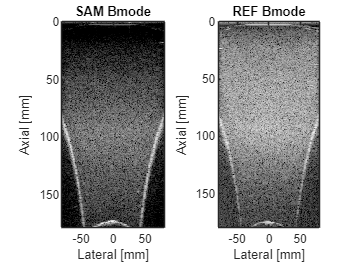

Bmode = @(RF) 20*log10(abs(hilbert(RF))) - max (20*log10(abs(hilbert(RF))));

Bmode_SAM = Bmode(SAM.RF_data); % SAM.axial y SAM.lateral in mm
Bmode_REF = Bmode(REF.RF_data); % REF.axial y REF.lateral in mm

figure,
subplot 121,
imagesc(SAM.lateral, SAM.axial, Bmode_SAM), colormap("gray")
title('SAM Bmode'), xlabel('Lateral [mm]'), ylabel('Axial [mm]');
set(gca, 'clim', [-60 0])
subplot 122,
imagesc(REF.lateral, REF.axial, Bmode_REF), colormap("gray")
title('REF Bmode'), xlabel('Lateral [mm]'), ylabel('Axial [mm]');
set(gca, 'clim', [-60 0])

## 2. ACS & BSC MEASUREMENTS

### 2.1. ACS SAMPLE and REFERENCE

%Bande frequentiel de calcul
P = 2^10; % number of points (powers of 2)
fct = 1e6; % for MHz
BW = [1.6 4.7];  % update depending the Power Spectra
BW = [1.7 4];  % update depending the Power Spectra
fs = 40E6; % 40 MHz
Np2dB = 8.6858; % To convert Np to dB
% fun_Np2dB = @(x) 8.6858*x;
% fun_dB2Np = @(x) x/8.6858;

Xfreq = (0 : (P/2-1))*fs/(P*fct);    % [MHz]                           
lambda_sam = SAM.parameters.c/(mean([BW(1) BW(2)])*fct); % [wavelength]
lambda_ref = REF.parameters.c/(mean([BW(1) BW(2)])*fct); % [wavelength]

fprintf('\nCalculation bandwidth SAMPLE:\nBW = %g - %g MHz, Fc = %g MHz\nwavelength (wl) = %g mm\n', BW(1), BW(2), mean([BW(1) BW(2)]), lambda_sam*1e3);


Calculation bandwidth SAMPLE:
BW = 1.7 - 4 MHz, Fc = 2.85 MHz
wavelength (wl) = 0.536842 mm


fprintf('\nCalculation bandwidth REFERENCE:\nBW = %g - %g MHz, Fc = %g MHz\nwavelength (wl) = %g mm\n', BW(1), BW(2), mean([BW(1) BW(2)]), lambda_ref*1e3);


Calculation bandwidth REFERENCE:
BW = 1.7 - 4 MHz, Fc = 2.85 MHz
wavelength (wl) = 0.540351 mm



Fi = find(Xfreq >= BW(1));
Ff = find(Xfreq >= BW(2));
band_ind = Fi(1) : Ff(1);            % [sample]
band = band_ind*fs/(fct*P);          % [MHz]
band_k = 2*pi*band*fct/SAM.parameters.c;   % [rad/s]

% Choice of window type
window_type = 2; % 1. Hanning, 2. Tuckey-0.25, 3. Hamming, 4. Chebyshev
        
% Transmisson coefficient for Saran layer
% TT = transmission_saran(band);

% Attenuation of the sample phantom

ATT_sam = attenuation_phantoms_Np(band, phantomSamInfo.numPhantom); % [Np/cm]
[alpha_sam, ~, y_lin_sam, ~] = fit_linear(band, Np2dB*ATT_sam', 2);  % [dB/cm.MHz]

fprintf('ACS sample = %.4f dB/cm.Hz\n', alpha_sam);

ACS sample = 0.3007 dB/cm.Hz


% Attenuation of the reference phantom
ATT_ref = attenuation_phantoms_Np(band, phantomRefInfo.numPhantom); % [Np/cm]
[alpha_ref, ~, y_lin_ref, ~] = fit_linear(band, Np2dB*ATT_ref', 2); % [dB/cm.MHz]

fprintf('ACS reference = %.4f dB/cm.Hz\n', alpha_ref);

ACS reference = 0.6851 dB/cm.Hz


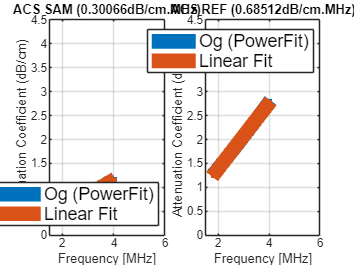


% PLOTS
figure,

subplot 121,
plot(band, Np2dB*ATT_sam', '.-', 'LineWidth', 10), hold on;
plot(band, y_lin_sam, '.-', 'LineWidth', 10), grid on, hold off;
xlabel('Frequency [MHz]'), ylabel('Attenuation Coefficient (dB/cm)'),
title(['ACS SAM (', num2str(alpha_sam), 'dB/cm.MHz)']), ylim([0 4.5]), xlim([1.5 6]);
legend('Og (PowerFit)', 'Linear Fit', 'Location', 'SouthEast', 'Fontsize', 12);

subplot 122,
plot(band, Np2dB*ATT_ref', '.-', 'LineWidth', 10), hold on;
plot(band, y_lin_ref, '.-', 'LineWidth', 10), grid on, hold off;
xlabel('Frequency [MHz]'), ylabel('Attenuation Coefficient (dB/cm)'),
title(['ACS REF (', num2str(alpha_ref), 'dB/cm.MHz)']), ylim([0 4.5]), xlim([1.5 6]);
legend('Og (PowerFit)', 'Linear Fit', 'Location', 'NorthEast', 'Fontsize', 12);

% fontsize(gcf, 20, 'points')



### 2.2. BSC SAMPLE and REFERENCE

fileNameBSC_sam = ['BSC_vs_freq_P', num2str(phantomSamInfo.numPhantom),'.txt']

fileNameBSC_sam = 'BSC_vs_freq_P22.txt'

fileNameBSC_ref = ['BSC_vs_freq_P', num2str(phantomRefInfo.numPhantom),'.txt']

fileNameBSC_ref = 'BSC_vs_freq_P20.txt'

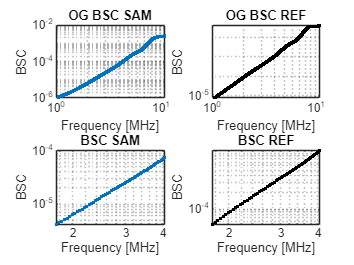

file_BSCsam = readmatrix(fileNameBSC_sam); % Freq, BSC
file_BSCref = readmatrix(fileNameBSC_ref); % Freq, BSC

% freqs | bsc
% BSC_sam = interp1(freqs, bsc, band);
BSC_sam = interp1(file_BSCsam(:,1), file_BSCsam(:,2), band);
BSC_ref = interp1(file_BSCref(:,1), file_BSCref(:,2), band);
% clear file_BSCref file_BSCsam

% PLOTS
figure,
subplot 221,
loglog(file_BSCsam(:,1), file_BSCsam(:,2), '.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('OG BSC SAM')

subplot 222,
loglog(file_BSCref(:,1), file_BSCref(:,2), 'k.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('OG BSC REF')

subplot 223,
loglog(band, BSC_sam, '.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('BSC SAM')

subplot 224,
loglog(band, BSC_ref, 'k.-'), grid minor;
xlabel('Frequency [MHz]'), ylabel('BSC'),
title('BSC REF')

### **REF PHANTOM METHOD (RPM)**


%%%% FORMATING SAMPLE TO DATA_RPM %%%%
DATA_RPM.RF = SAM.RF_data; 
DATA_RPM.x = SAM.lateral/1e3; % was in [mm] to [m]
DATA_RPM.z = SAM.axial/1e3; % was in [mm] to [m]
DATA_RPM.c = SAM.parameters.c; % [m/s]
% DATA.Bmode = Bmode(SAM.RF_data);
DATA_RPM.Bmode = Bmode_SAM;
DATA_RPM.fs = fs;

%%%% FORMATING REFERENCE TO REF_RPM %%%%
REF_RPM.RF = REF.RF_data; 
REF_RPM.x = REF.lateral/1e3; % was in [mm] to [m]
REF_RPM.z = REF.axial/1e3; % was in [mm] to [m]
REF_RPM.c = REF.parameters.c; % [m/s]
REF_RPM.fs = fs;

%%%% FORMATING PARAMETERS %%%%
pars.BW = BW;
pars.P = P;
pars.nb_lambda_axial = 20;
pars.overlap_axial = 0.8;
pars.overlap_lateral = 0.8;
pars.REF_num = phantomRefInfo.numPhantom;
pars.SAM_num = phantomSamInfo.numPhantom;
pars.BSC_ref = BSC_ref;

pars.z_ini = 30e-3; % in [m]
pars.z_end = 100e-3; % in [m]

pars.x_ini = -50e-3; %in [m]
pars.x_end = 50e-3; %in [m]


[BSC] = calculateBSC_RPM(DATA_RPM, REF_RPM, pars, Bmode_SAM)

Unrecognized function or variable 'caculateBSC_RPM'.



%%%

% BSC RESULTS
linewidth = 3;

figure,
set(gcf,'units','normalized','outerposition',[0 0 1 1]);
loglog(band, BSC.BSCcurve_Uni(:,2)', '.-', 'LineWidth', linewidth+1), hold on
loglog(band, BSC_sam, 'k.-', 'LineWidth', linewidth), grid minor;

xlabel('Frequency [MHz]'), ylabel('BSC [1/(sr.cm)]')
title(['BSC P', num2str(numPhantomSam)])
legend ('BSC', 'Ground truth','Location', 'SouthEast')
fontsize(gcf, 40, 'points')

% saveas (gcf, ['.\Results\BSC_P', num2str(phantomSamInfo.numPhantom), '_', phantomSamInfo.operator, ...
%     '_F', phantomSamInfo.freqChar, 'MHz_', ...
%      num2str(phantomSamInfo.numCase), '.png' ])



% MEAN DIFFERENCE OF FIT IN dB
diff_fit_dB = mean ( abs ( 10*log10(BSC_sam) - 10*log10(BSC.BSCcurve_Uni(:,2)') ) );

disp(diff_fit_dB)


my_table = cell2table( num2cell( [band', BSC.BSCcurve_Uni(:,2), BSC_sam' ]) );


## ACS ORIGINAL

% PLOTS WITH NUMBER PHANTOM INFO
% figure,
% set(gcf,'units','normalized','outerposition',[0 0 1 1]);
% linewidth = 3;
% subplot 121,
% plot(band, Np2dB*ATT_sam', '.-', 'LineWidth', linewidth), hold on;
% plot(band, y_lin_sam, '.-', 'LineWidth', linewidth), grid on, hold off;
% xlabel('Frequency [MHz]'), ylabel('Attenuation Coefficient (dB/cm)'),
% title(['ACS P', num2str(numPhantomSam), ' (', num2str(alpha_sam), 'dB/cm.MHz)']), ylim([0 4.5]), xlim([1.5 6]);
% legend('Og (PowerFit)', 'Linear Fit', 'Location', 'SouthEast', 'Fontsize', 12);
% 
% subplot 122,
% plot(band, Np2dB*ATT_ref', '.-', 'LineWidth', linewidth), hold on;
% plot(band, y_lin_ref, '.-', 'LineWidth', linewidth), grid on, hold off;
% xlabel('Frequency [MHz]'), ylabel('Attenuation Coefficient (dB/cm)'),
% title(['ACS P', num2str(numPhantomRef), ' (', num2str(alpha_ref), 'dB/cm.MHz)']), ylim([0 4.5]), xlim([1.5 6]);
% legend('Og (PowerFit)', 'Linear Fit', 'Location', 'SouthEast', 'Fontsize', 12);
% 
% fontsize(gcf, 30, 'points')
% 
% saveas (gcf, ['.\Results\ACS_P20-P22_',num2str(BW(1)), '-', num2str(BW(2)), 'MHz.png']);

## BSC ORIGINAL

%  ORIGINAL BSC
% PLOTS

% figure,
% set(gcf,'units','normalized','outerposition',[0 0 1 1]);
% 
% linewidth = 7;
% subplot 121,
% loglog(file_BSCsam(:,1), file_BSCsam(:,2), '.-', 'LineWidth', linewidth), grid minor;
% xlabel('Frequency [MHz]'), ylabel('BSC [1/(sr.cm)]'), ylim([10^-6 10^-1]), xlim([1 10.5]),
% title(['BSC P', num2str(numPhantomSam)])
% 
% subplot 122,
% loglog(file_BSCref(:,1), file_BSCref(:,2), 'k.-', 'LineWidth', linewidth), grid minor;
% xlabel('Frequency [MHz]'), ylabel('BSC [1/(sr.cm)]'), ylim([10^-6 10^-1]), xlim([1 10.5]),
% title(['BSC P', num2str(numPhantomRef)])
% 
% fontsize(gcf, 30, 'points')

% saveas (gcf, '.\Results\BSC_P20-P22_1-10MHz.png');

### PLOT & SAVE BMODE

% VERSION 2
% min(find(SAM.axial>=80))


% linewidth = 7;
% 
% figure,
% set(gcf,'units','normalized','outerposition',[0 0 1 1]);
% subplot 121,
% imagesc(SAM.lateral/10, SAM.axial/10, Bmode_SAM), colormap("gray"), hold on;
% rectangle('Position', 1e2*[pars.x_ini pars.z_ini pars.x_end-pars.x_ini pars.z_end-pars.z_ini], 'EdgeColor','r', 'LineWidth', linewidth)
% 
% title(['P', num2str(numPhantomSam),' Bmode']), xlabel('Lateral [cm]'), ylabel('Axial [cm]');
% set(gca, 'clim', [-60 0])
% 
% 
% subplot 122,
% imagesc(REF.lateral/10, REF.axial/10, Bmode_REF), colormap("gray"), hold on;
% rectangle('Position', 1e2*[pars.x_ini pars.z_ini pars.x_end-pars.x_ini pars.z_end-pars.z_ini], 'EdgeColor','r', 'LineWidth', linewidth)
% 
% title(['P', num2str(numPhantomRef),' Bmode']), xlabel('Lateral [cm]'), ylabel('Axial [cm]');
% set(gca, 'clim', [-60 0])
% 
% fontsize(gcf, 30, 'points')
% 
% saveas (gcf, '.\Results\Bmode_P20-P22.png');

% 

% figure, 
% plot (band, log10(BSC_sam), 'k.-', 'LineWidth', linewidth), hold on;
% % plot (band, 6.5e-6*band.^3.71, 'r.-', 'LineWidth', linewidth)
% 
% figure,
% h = subimage(X_ROI, Z_ROI, 256*mat2gray(CData_Uni, [-6 -4]), jet(256));
% colormap(jet(256));
%         h2 = colorbar;
%         clim([-6 -4])
%         ylabel(h2,'sr^{-1}cm^{-1}','FontSize', 14);
% 
% figure,
% imshow(X_ROI, Z_ROI, 256*mat2gray(CData_Uni, [-6 -4]), jet(256));
% colormap(jet(256));
%         h2 = colorbar;
%         ylabel(h2,'sr^{-1}cm^{-1}','FontSize', 14);        
% 
%         figure,
% h = subimage(X_ROI, Z_ROI, 256*(CData_Uni, [-6 -4]), jet);
% colormap jet
%         h2 = colorbar;
%         ylabel(h2,'sr^{-1}cm^{-1}','FontSize', 14);
% 
% 
%                 figure
%         subplot(121)
%         imagesc(X_ROI,Z_ROI,CData_Uni, [-6 -4]), colormap(jet(256))
% %                imagesc(X_ROI,Z_ROI,CData_Uni)
%         xlabel('\bfLateral distance [cm]','fontsize',12);
%         ylabel('\bfAxial distance [cm]','fontsize',12)
%         title(['\bfiBSC = ' num2str(av_iBSC_Uni, '%.2s' ) ' \pm' num2str(sd_iBSC_Uni, '%.2s' ) ' sr^{-1}cm^{-1}']);
%         colorbar
%         subplot(122)
%         imagesc(X_ROI,Z_ROI,(Integ_BSC_Uni), [6e-6 15e-6])
%         xlabel('\bfLateral distance [cm]','fontsize',12);
%         ylabel('\bfAxial distance [cm]','fontsize',12)
%         title(['\bfPrev-iBSC = ' num2str(av_iBSC_Uni, '%.2s' ) ' \pm' num2str(sd_iBSC_Uni, '%.2s' ) ' sr^{-1}cm^{-1}']);
%         colorbar


function [phantomInfo] = selectPhantom(operator, numPhantom, freqValue)

%%%% MATCH PHANTOM INFORMATION ACCORDING TO SPECS %%% 
% function [phantomInfo] = selectPhantom(operator, numPhantom, freqValue)
% Example: operator = 'AH' | 'ZT', numPhantom = 20 | 22, freqValue = 2.5 | 4.0 | 5.5

%%% PHANTOM 20 %%%
% FREQ = [2.5 4.0 5.5]
% CASE = [130640 130724 130825]
%%% PHANTOM 22 %%%
% FREQ = [2.5 4.0 5.5]
% CASE = [134425 134447 134610]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%% OPERATOR ZT %%%

%%% PHANTOM 20 %%%
% FREQ = [2.5 4.0 5.5]
% CASE = [133512 133529 133609]

%%% PHANTOM 22 %%%
% FREQ = [2.5 4.0 5.5]
% CASE = [140408 140427 140503]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


FREQ = ["2.5", "4.0", "5.5"]; % [MHz]

lchar_freq = cell2mat(convertStringsToChars(FREQ(:)));
lnum_freq = str2num(lchar_freq);

idx = find(lnum_freq == freqValue);

if strcmp(operator, 'AH')
    if (numPhantom == 20)
        list_case = [130640 130724 130825];
        freqChar = lchar_freq(idx,:);
        numCase = list_case(idx);
    end 
    if (numPhantom == 22)
        list_case = [134425 134447 134610];
        freqChar = lchar_freq(idx,:);
        numCase = list_case(idx);
    end
end

if strcmp(operator, 'ZT')
    if (numPhantom == 20)
        list_case = [133512 133529 133609];
        freqChar = lchar_freq(idx,:);
        numCase = list_case(idx);
    end
    if (numPhantom == 22)
        list_case = [140408 140427 140503];
        freqChar = lchar_freq(idx,:);
        numCase = list_case(idx);
    end 
end

phantomInfo.operator = operator;
phantomInfo.numPhantom = numPhantom;
phantomInfo.freqChar = freqChar;
phantomInfo.numCase = numCase;

end